# Example MF-Tyre Library Fitter FSAE TTC

This example interactively guides you through fitting and exporting an MF-Tyre model to measurement data acquired from the [FSAE Tire Test Consortium (TTC)](https://www.fsaettc.org/). The process would be similar with data from other sources, but the user would have to write their own parser (input data --> `tydex.Measurement`).

## Import Measurement Data

### Select Measurement File (FSAE TTC .mat)

[filename, filedir] = uigetfile('*.mat', 'Select FSAE TTC measurement file');
file = fullfile(filedir, filename);
try
    data = load(file);
    assert(all(isfield(data, {'FX','FY','FZ'})))
    clear data
catch ME
    clear data
    error('Invalid measurement file. This example only works with FSAE TTC measurements in MAT file format.')
end

### Parse Measurement File into TYDEX Measurement Objects

FSAE TTC usually tests either

- Drive / Brake (Varying but steady-state slip angle, then slip ratio sweeps)

- Cornering (No slip ratio, but slip angle sweeps)

Select the parser that fits your measurement data:

parser = tydex.parsers.FSAETTC_SI_ISO_Mat_DriveBrake;
measurements = parser.run(file);

## Fit Model to Measurement Data

**Note:** Be aware that you cannot run the fitter in all fit-modes with just one measurement type. The FSAE TTC has two different test types and Fx0 can only be fitted with Drive/Brake typed tests, for example. Fy0 also works only with Cornering test types.

### Create MF-Tyre Model

tyreModel = mftyre.v62.Model();
params = tyreModel.Parameters;

### Prepare Parameters for Fitting

General model parameters:

params.NOMPRES.Value = measurements(1).NOMPRES;
params.FNOMIN.Value = measurements(1).FNOMIN;

Fy0 parameters:

params.PCY1.Min = 1;      params.PCY1.Max = 2;  params.PCY1.Value = 1.9;

params.PDY1.Min = 0.1;      params.PDY1.Max = 5;    params.PDY1.Value = 0.8; 
params.PDY2.Min = -0.5;     params.PDY2.Max = 0;    params.PDY2.Value = -0.05; 
params.PDY3.Min = -10;      params.PDY3.Max = 10;   params.PDY3.Value = 0;      params.PDY3.Fixed = false; 

params.PEY1.Min = -100;     params.PEY1.Max = 100;  params.PEY1.Value = -0.8;
params.PEY2.Min = -100;     params.PEY2.Max = 100;  params.PEY2.Value = -0.6;
params.PEY3.Min;            params.PEY3.Max;        params.PEY3.Value = 0.1;    params.PEY3.Fixed = false;
params.PEY4.Min;            params.PEY4.Max;        params.PEY4.Value = 0;      params.PEY4.Fixed = false;
params.PEY5.Min;            params.PEY5.Max;        params.PEY5.Value = 0;      params.PEY5.Fixed = false;

params.PKY1.Min = -100;     params.PKY1.Max = -5;   params.PKY1.Value = -20;
params.PKY2.Min = -5;       params.PKY2.Max = 5;    params.PKY2.Value = 2;
params.PKY3.Min = -1;       params.PKY3.Max = 1;    params.PKY3.Value = 0;
params.PKY4.Min = 1.05;     params.PKY4.Max = 2;    params.PKY4.Value = 2;      params.PKY4.Fixed = true;
params.PKY5.Min;            params.PKY5.Max;        params.PKY5.Value = 0;      params.PKY5.Fixed = false;
params.PKY6.Min;            params.PKY6.Max;        params.PKY6.Value = 0;      params.PKY6.Fixed = false;
params.PKY7.Min;            params.PKY7.Max;        params.PKY7.Value = 0;      params.PKY7.Fixed = false;

params.PHY1.Min;            params.PHY1.Max;        params.PHY1.Value = 0;      params.PHY1.Fixed = false;
params.PHY2.Min;            params.PHY2.Max;        params.PHY2.Value = 0;      params.PHY2.Fixed = false;

params.PVY1.Min;            params.PVY1.Max;        params.PVY1.Value = 0;      params.PVY1.Fixed = false;
params.PVY2.Min;            params.PVY2.Max;        params.PVY2.Value = 0;      params.PVY2.Fixed = false;
params.PVY3.Min;            params.PVY3.Max;        params.PVY3.Value = 0;      params.PVY3.Fixed = false;
params.PVY4.Min;            params.PVY4.Max;        params.PVY4.Value = 0;      params.PVY4.Fixed = false;

params.PPY1.Min = -2;       params.PPY1.Max = 2;    params.PPY1.Value = 0.1;
params.PPY2.Min = -2;       params.PPY2.Max = 2;    params.PPY2.Value = 0.1;
params.PPY3.Min = -1;       params.PPY3.Max = 1;    params.PPY3.Value = 0;      params.PPY3.Fixed = false;
params.PPY4.Min = -2;       params.PPY4.Max = 1;    params.PPY4.Value = 0;      params.PPY4.Fixed = false;
params.PPY5.Min;            params.PPY5.Max;        params.PPY5.Value = 0;      params.PPY5.Fixed = false;

Fx0 parameters:

params.PCX1.Min = 1.5;      params.PCX1.Max = 2;    params.PCX1.Value = 1.9;

params.PDX1.Min = 1;        params.PDX1.Max = 5;    params.PDX1.Value = 2;
params.PDX2.Min = -1;       params.PDX2.Max = 0;    params.PDX2.Value = -0.01;
params.PDX3.Min = 0;        params.PDX3.Max = 15;   params.PDX3.Value = 10;     params.PDX3.Fixed = false;

params.PEX1.Min = -100;     params.PEX1.Max = 0;    params.PEX1.Value = -1;
params.PEX2.Min = -3;       params.PEX2.Max = 3;    params.PEX2.Value = 0.3;
params.PEX3.Min = -0.6;     params.PEX3.Max = 0.6;  params.PEX3.Value = 0;      params.PEX3.Fixed = true;
params.PEX4.Min = -0.9;     params.PEX4.Max = 0.9;  params.PEX4.Value = 0;      params.PEX4.Fixed = true;

params.PKX1.Min = 5;        params.PKX1.Max = 100;  params.PKX1.Value = 20;
params.PKX2.Min = -30;      params.PKX2.Max = 30;   params.PKX2.Value = 10;
params.PKX3.Min = -10;      params.PKX3.Max = 10;   params.PKX3.Value = 0;      params.PKX3.Fixed = false;

params.PHX1.Min = -0.1;     params.PHX1.Max = 0.1;  params.PHX1.Value = 0;      params.PHX1.Fixed = false;
params.PHX2.Min = -0.1;     params.PHX2.Max = 0.1;  params.PHX2.Value = 0;      params.PHX2.Fixed = false;

params.PVX1.Min = -0.1;     params.PVX1.Max = 0.1;  params.PVX1.Value = 0;      params.PVX1.Fixed = false;
params.PVX2.Min = -0.1;     params.PVX2.Max = 0.1;  params.PVX2.Value = 0;      params.PVX2.Fixed = false;

Fx parameters.

params.RCX1.Min = -1;       params.RCX1.Max = 1.2;  params.RCX1.Value = 1;

params.RBX1.Min = 5;        params.RBX1.Max = 50;   params.RBX1.Value = 5;
params.RBX2.Min = 5;        params.RBX2.Max = 50;   params.RBX2.Value = 5;
params.RBX3.Min;            params.RBX3.Max;        params.RBX3.Value = 0;      params.RBX3.Fixed = false;

params.REX1.Min = -10;      params.REX1.Max = 1;    params.REX1.Value = -1;
params.REX2.Min = -5;       params.REX2.Max = 1;    params.REX2.Value = -0.1;

params.RHX1.Min;            params.RHX1.Max;        params.RHX1.Value;          params.RHX1.Fixed = false;

Fy parameters:

params.RCY1.Min = 0.8;      params.RCY1.Max = 2;    params.RCY1.Value = 1;

params.REY1.Min = -6;       params.REY1.Max = 1;    params.REY1.Value = -0.1;
params.REY2.Min = -1;       params.REY2.Max = 5;    params.REY2.Value = 0.1;

params.RBY1.Min = 2;        params.RBY1.Max = 40;   params.RBY1.Value = 5;
params.RBY2.Min = 2;        params.RBY2.Max = 40;   params.RBY2.Value = 2;
params.RBY3.Min = -0.15;    params.RBY3.Max = 0.15; params.RBY3.Value = 0.02;
params.RBY4.Min = -90;      params.RBY4.Max = 90;   params.RBY4.Value = 0;      params.RBY4.Fixed = false;

params.RHY1.Min;            params.RHY1.Max;        params.RHY1.Value = 0;      params.RHY1.Fixed = false;
params.RHY2.Min;            params.RHY2.Max;        params.RHY2.Value = 0;      params.RHY2.Fixed = false;

params.RVY1.Min;            params.RVY1.Max;        params.RVY1.Value = 0;      params.RVY1.Fixed = false;
params.RVY2.Min;            params.RVY2.Max;        params.RVY2.Value = 0;      params.RVY2.Fixed = false;
params.RVY3.Min;            params.RVY3.Max;        params.RVY3.Value = 0;      params.RVY3.Fixed = false;
params.RVY4.Min;            params.RVY4.Max;        params.RVY4.Value = 0;      params.RVY4.Fixed = false;
params.RVY5.Min;            params.RVY5.Max;        params.RVY5.Value = 0;      params.RVY5.Fixed = false;
params.RVY6.Min;            params.RVY6.Max;        params.RVY6.Value = 0;      params.RVY6.Fixed = false;

### Run Fitter

Select the fitting modes you want to execute. Currently only longitudinal and lateral tyre forces are supported. Depending on your data, you might not be able to execute all fitmodes.

fitmodes = [
    mftyre.v62.FitMode.Fx0
    % mftyre.v62.FitMode.Fy0
    mftyre.v62.FitMode.Fx
    % mftyre.v62.FitMode.Fy
    ];

Run fitter:

fitter = mftyre.v62.Fitter(measurements, params);
fitter.FitModes = fitmodes;
fitter.Options.MaxFunctionEvaluations = 10000;
fitter.run()

Starting MF-Tyre fitter...
Fitting Fit-Mode: Fx0
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      23    6.167747e+09    0.000e+00    3.310e+09
    1      51    5.968481e+09    0.000e+00    1.541e+10    2.317e+00
    2      76    5.749620e+09    0.000e+00    5.980e+10    4.209e-01
    3      99    4.708220e+09    0.000e+00    2.836e+10    3.840e-01
    4     123    4.680944e+09    0.000e+00    2.839e+10    1.042e+00
    5     147    4.064021e+09    0.000e+00    2.969e+10    2.032e+01
    6     171    2.335278e+09    0.000e+00    2.057e+10    1.457e+01
    7     196    2.290416e+09    0.000e+00    2.063e+10    3.552e+00
    8     219    2.077015e+09    0.000e+00    2.067e+10    9.154e+00
    9     244    1.888836e+09    0.000e+00    3.052e+10    2.798e+00
   10     268    1.864621e+09    0.000e+00    2.193e+10    3.613e+00
   11     291    1.450496e+09    0.000e+00    2.398e+10    5.409e+0

Result can be accessed from public property:

paramsFitted = fitter.ParametersFitted;

## Test fitted model:

Select some measurement:

m = measurements(end);

Calculate model:

p = struct(paramsFitted);
SA = m.SLIPANGL;
SX = m.LONGSLIP;
IA = m.INCLANGL;
P = m.INFLPRES;
FZ = m.FZW;
[FX, FY] = mftyre.v62.eval(p, SA, SX, IA, P, FZ, 0);

Plot against model:

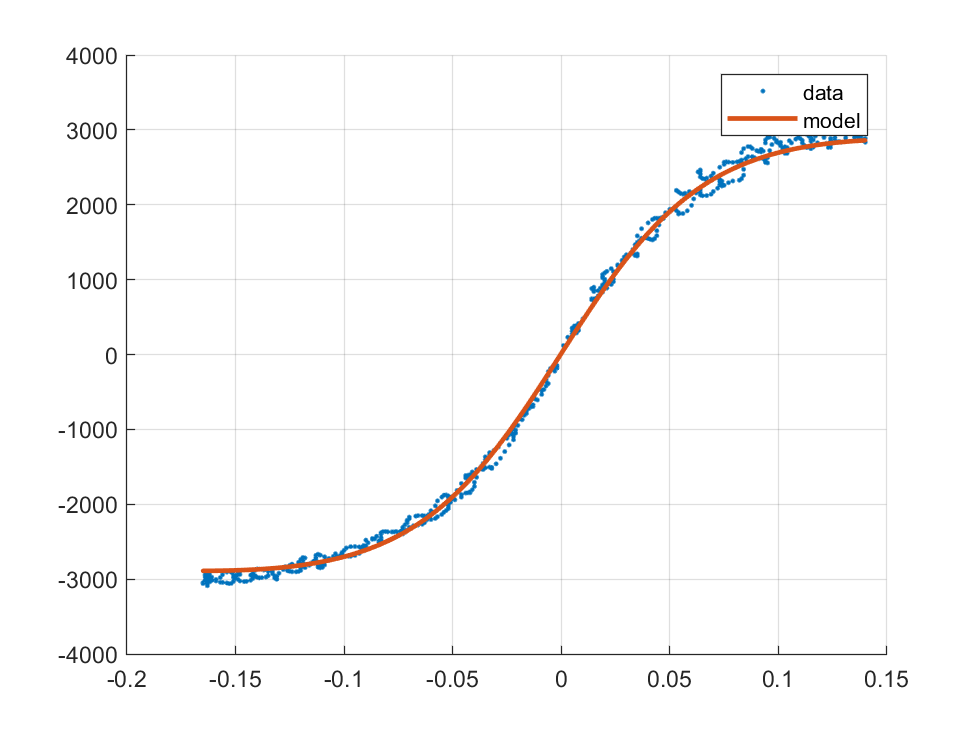

constants = {m.Constant.Name};
figure
grid on
hold on
if any(contains(constants, 'SLIPANGL'))
    plot(m.LONGSLIP, m.FX, '.')
    plot(m.LONGSLIP, FX, '-', 'LineWidth', 2)
else
    plot(m.SLIPANGL, m.FYW, '.')
    plot(m.SLIPANGL, FY, '-', 'LineWidth', 2)
end
legend data model

If the model fit is not satisfactory, try altering the min/max settings above or the initial values.

## Export Fitted Model

First, update the tyre model with the fitted parameter set:

tyreModel.Parameters = paramsFitted;

### Export as Tyre Property File (.tir)

% tyreModel.exportTyrePropertiesFile('mftyre62_test.tir')

### Export to Struct

paramsStruct = struct(tyreModel.Parameters);

Optionally, save to MAT:

% save mftyre62_test.tir paramsStruct